# Multiple Linear Regression

### Go-SHIP line P18

close all
clear all

data=csvread('33RO20161119_hy1.csv',152,2);
stn=data(:,1);
lat=data(:,8);
lon=data(:,9);
p=data(:,11);
t=data(:,12);
sp=data(:,13);
o2=data(:,19);
no3=data(:,23);

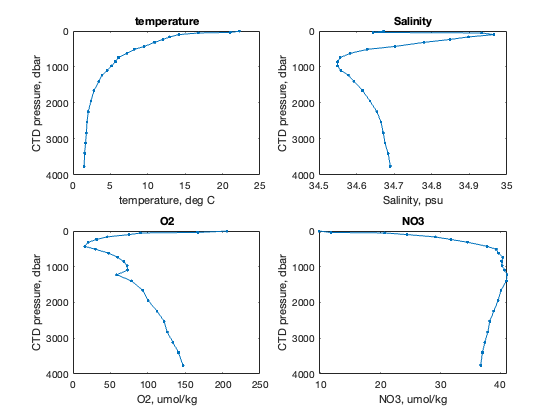

% quick look at a single station
ind = (stn==50);
% 
subplot(2,2,1)
plot(t(ind),p(ind),'.-');
xlabel('temperature, deg C')
title('temperature')
ylabel('CTD pressure, dbar')
set(gca,'Ydir','rev')
%
subplot(2,2,2)
plot(sp(ind),p(ind),'.-')
xlabel('Salinity, psu')
title('Salinity')
ylabel('CTD pressure, dbar')
set(gca,'Ydir','rev')
% 
subplot(2,2,3)
plot(o2(ind),p(ind),'.-')
xlabel('O2, umol/kg')
title('O2')
ylabel('CTD pressure, dbar')
set(gca,'Ydir','rev')
% 
subplot(2,2,4)
plot(no3(ind),p(ind),'.-')
xlabel('NO3, umol/kg')
title('NO3')
set(gca,'Ydir','rev')
ylabel('CTD pressure, dbar')

### Can we use multiple linear regression to estimate NO3 as a function of (T,S,P,O2)?

% Use station 50 to establish a relationship 
% 
ind=(stn==50);
N=sum(ind);
A=ones(N,5);
b=zeros(N,1);
A(:,1)=t(ind);
A(:,2)=sp(ind);
A(:,3)=p(ind);
A(:,4)=o2(ind);
b=no3(ind);
xvec=A\b;

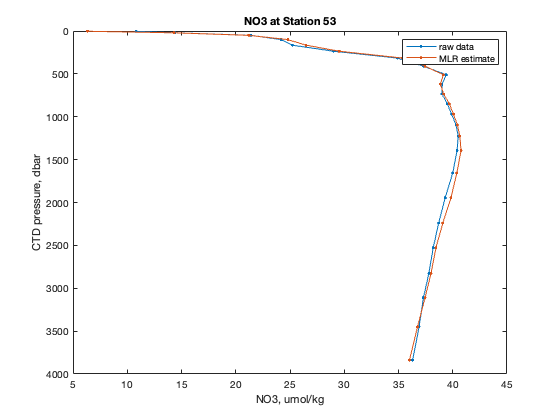

% validate using a station
% 
STN=53;
ind = (stn==STN);
N=sum(ind);
A=ones(N,5);
A(:,1)=t(ind);
A(:,2)=sp(ind);
A(:,3)=p(ind);
A(:,4)=o2(ind);
cest=A*xvec;
%
% quick look at a single station
figure;
plot(no3(ind),p(ind),'.-');
hold on;
plot(cest,p(ind),'.-');
xlabel('NO3, umol/kg')
legend({'raw data' 'MLR estimate'});
set(gca,'Ydir','rev')
title(['NO3 at Station ',num2str(STN)]);
ylabel('CTD pressure, dbar');